# Sample script of learnableScaleLayer

 Copyright (c) Shogo MURAMATSU, 2021

 All rights reserved.


type learnableScalingLayer

classdef learnableScalingLayer < nnet.layer.Layer
    % LEARNABLESCALINGLAYER
    % 
    % Copyright (c) Shogo MURAMATSU, 2021
    % All rights reserved.
    % 
    
    properties(Learnable)
        % Layer learnable parameters
        Scale
    end
    
    methods
        function layer = learnableScalingLayer(varargin) 
            p = inputParser;
            addParameter(p,'Name','')
            addParameter(p,'Scale',1)
            parse(p,varargin{:})
            
            % Set layer name.
            layer.Name = p.Results.Name;
            
            % Initialize scaling coefficient.
            layer.Scale = p.Results.Scale;           
            layer.NumInputs = 1;

            % Set layer description.
            layer.Description = "Learnable scaling ( " + layer.Scale + " ).";
        end
        
        function Z = predict(layer, X)            
            Z = layer.Scale * X ;
        end
    end
end


layer = learnableScalingLayer('Name','scaling','Scale',2)

layer =   learnableScalingLayer のプロパティ:

     Name: 'scaling'

   学習可能パラメーター
    Scale: 2

  すべてのプロパティを表示


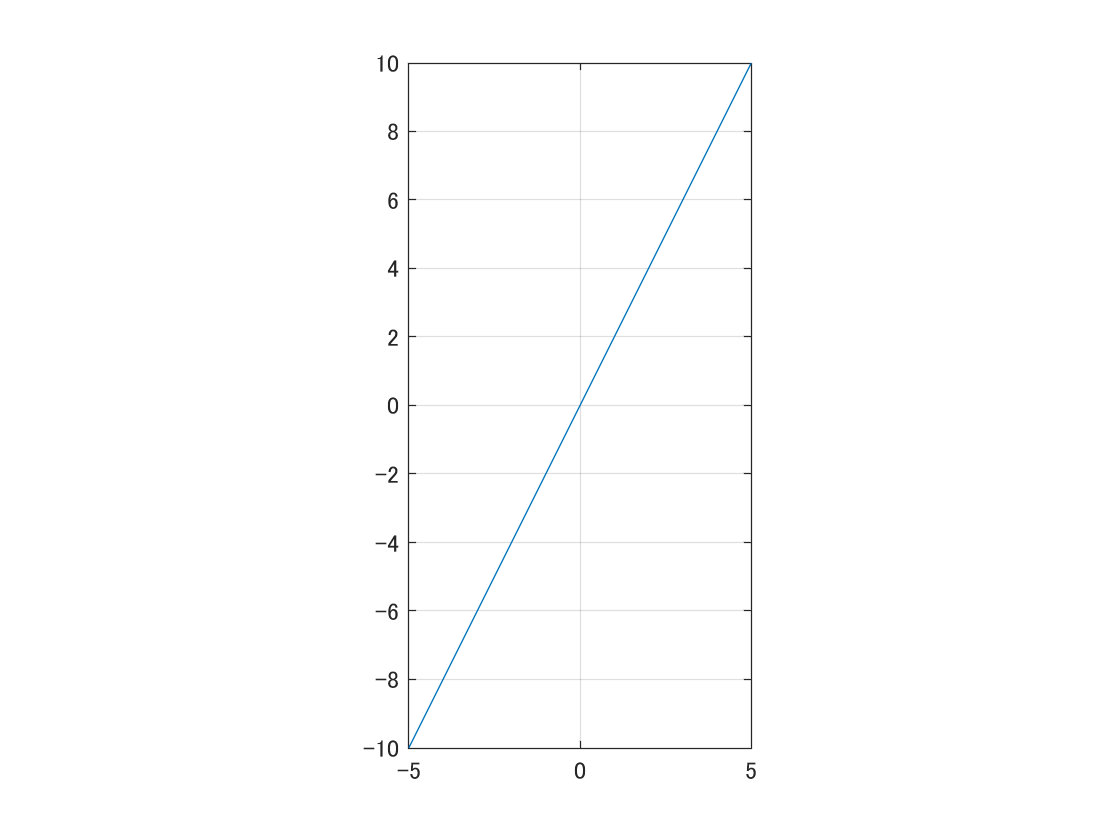


fplot(@(x) extractdata(layer.predict(dlarray(x))))
axis equal
grid on


checkLayer(layer,[24 24 20],'ObservationDimension',4)

コード生成互換性テストをスキップします。コード生成用の層の有効性をチェックするには、'CheckCodegenCompatibility' および 'ObservationDimension' オプションを指定します。
 
nnet.checklayer.TestLayerWithoutBackward を実行しています
.......... .......
nnet.checklayer.TestLayerWithoutBackward が完了しました
__________

テストの概要:
	 17 パス、0 失敗、0 未完了、5 スキップ。
	 経過時間: 0.21256 秒。
